# LAB 6

Arjun Gandhi, Christian Cooper, Ilyas Salhi

### Introduction

The goal of this lab was to combine everything we learned throughout the term and apply it to a relevant to life example. We have been progressively building on this problem for the last six labs. In this lab we took what we learned in class and applied a root locus analysis on the Cruise Control Car example that we worked in previous weeks. Running the root locus looks at how the roots of a system change when you vary a certain parameter. By doing this we can try and reduce the steady state error. 

#### 1)

clear;
close all;
% 𝑚𝑣̇ + 𝑏𝑣 = u
% U(s) = m(V(s)s-v(0)) + bV(s)
% U(s) /s+b) -m(v(0))
% openloop: V(s)/U(s) = 1/(ms+ b)
m = 1000;
b = 50; 
u = 500;


s = tf('s');
G = 1/(m*s + b) %Open loop

G =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.



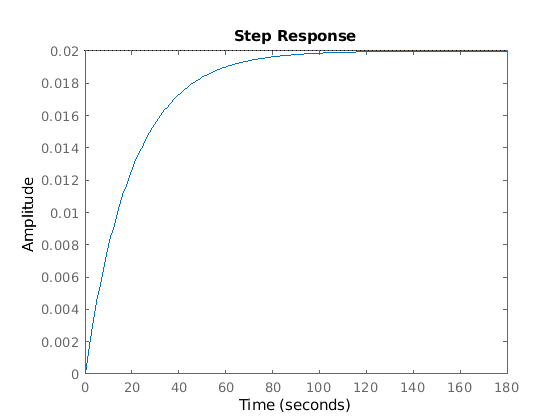

step(G)

transients=stepinfo(G)

transients = struct with fields:
        RiseTime: 43.9401
    SettlingTime: 78.2415
     SettlingMin: 0.0181
     SettlingMax: 0.0200
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0200
        PeakTime: 210.9168


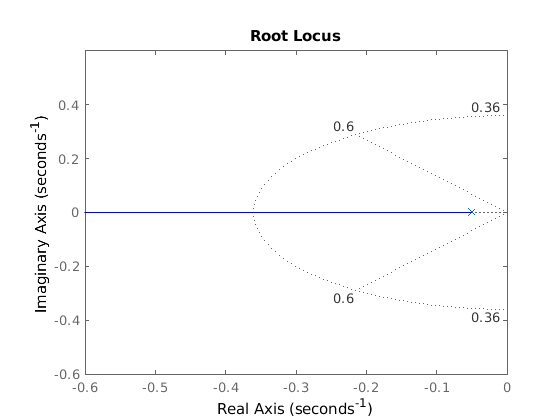

figure;
rlocus(G)
sgrid(0.6, 0.36)
axis([-0.6 0 -0.6 0.6] )

#### 2)

figure;
rlocus(G);
sgrid(0.6, 0.36);
axis([-0.6 0 -0.6 0.6] );
[Kp,~]=rlocfind(G)

Select a point in the graphics window


selected_point = -0.3996 + 0.0490i

Kp = 353.0051

close;

C = pid(Kp)

C =
 
  Kp = 353
 
P-only controller.



TF = feedback(G*C,1)

TF =
 
      353
  ------------
  1000 s + 403
 
Continuous-time transfer function.



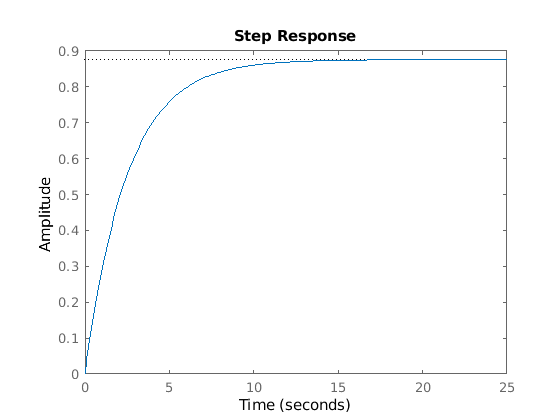

figure;
step(TF)

transients=stepinfo(TF)

transients = struct with fields:
        RiseTime: 5.4516
    SettlingTime: 9.7073
     SettlingMin: 0.7923
     SettlingMax: 0.8759
       Overshoot: 0
      Undershoot: 0
            Peak: 0.8759
        PeakTime: 26.1680


#### 3)

figure;
rlocus(TF);
sgrid(0.6, 0.36);
axis([-0.6 0 -0.6 0.6] );
[Kp,~]=rlocfind(TF)

Select a point in the graphics window


selected_point = -0.3971 + 0.0565i

Kp = 0.1610

close;


z0=0.3;
p0=0.03;
lag = (s+z0)/(s+p0)

lag =
 
  s + 0.3
  --------
  s + 0.03
 
Continuous-time transfer function.



TF = feedback(G*C*lag,1)

TF =
 
       353 s + 105.9
  ------------------------
  1000 s^2 + 433 s + 107.4
 
Continuous-time transfer function.



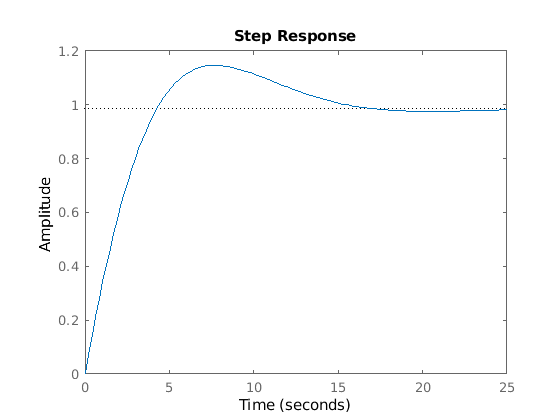

figure;
step(TF)

transients=stepinfo(TF)

transients = struct with fields:
        RiseTime: 3.2225
    SettlingTime: 15.1063
     SettlingMin: 0.9036
     SettlingMax: 1.1467
       Overshoot: 16.2960
      Undershoot: 0
            Peak: 1.1467
        PeakTime: 7.6575


The transient info shows that the peak time is smaller, and actually reaches its peak with a brief over shoot. 

### Conclusion

In this lab we applied what we learned in class and previous labs to take our Cruise Control Car example to another level. For example we found a gain to place the closed-loop poles in the desired region by employing the rlocfind command. After doing so we reduced the steady-state error even further by created a lag controller. Then after designing the controller we were able to look at the transient info .